# **Kalman Filter**

clear
clc
close all

## Lab4 - Part 1

% Read in measurments and plot for reference
fileID = fopen('1D-data.txt','r');
measurements = fscanf(fileID,'%f');
measurements  = measurements';
tt = linspace(1,639,639);

figure('Color','w');
plot(tt,measurements,'r-');
hold on

 Define kalman variables

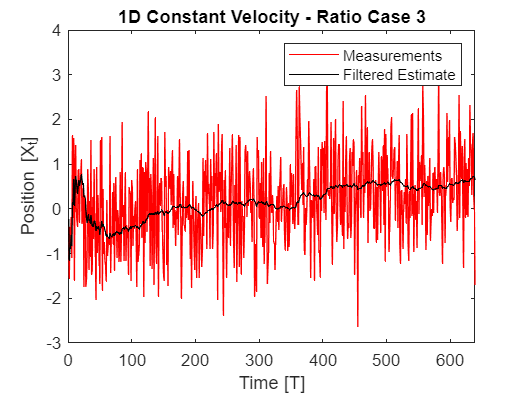

phi = [1 1;0 1]; %transition matrix
X = [0;0]; %Initial state definition (t-1,t-1)
S = [1 0;0 1]; %Initial state estimate covariance (t-1,t-1)
Q = [0 0; 0 0.0000001]; % Dynamic noise (prediction accuracy)
R = 1; % Measurement Noise (larger value means weight measurements less)
M = [1 0]; % observation matrix
I = [1 0;0 1]; % 2x2 identity matrix
for t = 1:1:length(measurements)
    Xt_t1 = phi*X;
    St_t1 = phi*S*phi'+Q;
    Yt = measurements(t);
    Kt = St_t1*M'*(M*St_t1*M' + R)^(-1);
    X = Xt_t1 + Kt*(Yt-M*Xt_t1);
    S = (I - Kt*M)*St_t1;
    X_plot(t) = X(1);
end
plot(tt,X_plot,'k-');
xlabel("Time [T]");
ylabel("Position [X_{t}]");
legend("Measurements","Filtered Estimate");
title("1D Constant Velocity - Ratio Case 3");

## Lab4 - Part 2

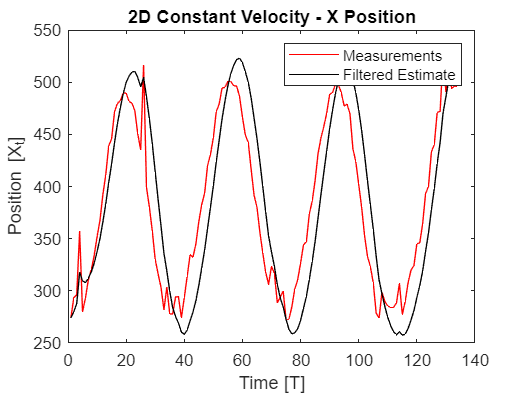

% Read in measurments and plot for reference
fileID = fopen('2D-UWB-data.txt','r');
measurments = fscanf(fileID,'%f %f',[2,Inf]);
measurments = measurments';
[r,c] = size(measurments);
tt = linspace(1,r,r);
% Define kalman variables
phi = [1 0 1 0;0 1 0 1;0 0 1 0;0 0 0 1]; %transition matrix
X = [measurments(1,1);measurments(1,2);0;0]; %Initial state definition (t-1,t-1)
S = [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]; %Initial state estimate covariance (t-1,t-1)
Q = [0 0 0 0;0 0 0 0;0 0 0.01 0.0001;0 0 0.0001 0.01]; % Dynamic noise (prediction accuracy)
R = [10 0.0001;0.0001 10]; % Measurement Noise (larger value means weight measurements less)
M = [1 0 0 0;0 1 0 0]; % observation matrix
I = [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]; % 2x2 identity matrix

for t = 1:1:length(measurments)
    Xt_t1 = phi*X;
    St_t1 = phi*S*phi'+Q;
    Yt(1,1) = measurments(t,1);
    Yt(2,1) = measurments(t,2);
    Kt = St_t1*M'*(M*St_t1*M' + R)^(-1);
    X = Xt_t1 + Kt*(Yt-M*Xt_t1);
    S = (I - Kt*M)*St_t1;
    X_plot(t,1) = X(1,1);
    X_plot(t,2) = X(2,1);
end

% Plot x measurements and filtered estimate
figure('Color','w');
plot(tt,measurments(:,1),'r-')
hold on 
plot(tt,X_plot(:,1),'k-')
xlabel("Time [T]");
ylabel("Position [X_{t}]");
legend("Measurements","Filtered Estimate");
title("2D Constant Velocity - X Position");

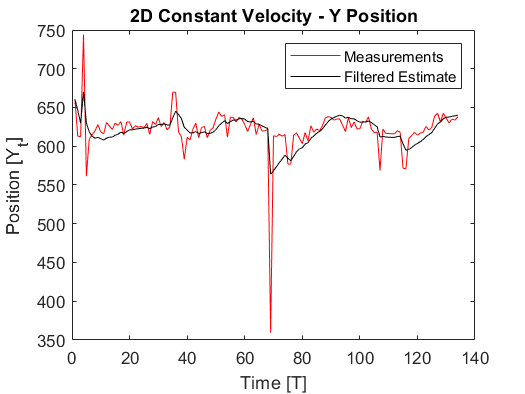


% Plot y measurements and filtered estimate
figure('Color','w');
plot(tt,measurments(:,2),'r-')
hold on 
plot(tt,X_plot(:,2),'k-')
xlabel("Time [T]");
ylabel("Position [Y_{t}]");
legend("Measurements","Filtered Estimate");
title("2D Constant Velocity - Y Position");